## Robust and Nonlinear Control, EEN050. 

### Assignment on robust controller design.

clear vars;
close all;
clc

Low fidelity F16 longitudinal model from Aircraft Control and Simulation (B.L.Stevens-F.L.Lewis) pp. 156.

The linearized dynamic of the airplane F16:

States: [ $V$ (ft/s) speed, $\alpha$ (rad) angle of attack, $\theta$ (rad) pitch angle, $q$ (rad/s) pitch rate, $T$ (lb) engine_power]

A=[-0.127 -235 -32.2 -9.51 0.314;-7E-4 -0.969 0 0.908 -2E-4;0 0 0 1 0; 9E-4 -4.56 0 -1.58 0;0 0 0 0 -5];

Control inputs: [thrust (N); elevator_deflection (rad)]

B=[0 -0.244;0 -0.00209; 0 0;10 -0.199; 1087 0];

Measured outputs: [ $\alpha$ (deg); $q$ (rad/s); normal_acceleration (ft/s^2) ]

C=[0 57.3 0 0 0;0 0 0 1 0;0.0208 15.2 0 1.45 0];

A small amount of direct feed through in D:

D=[0 0;0 0;0 0.033];

Note: elevator deflection has a direct effect on vertical/normal accelleration.

Q: How do we know if it is [r w]^T or [w r]^T when using ss?

Gn=ss(A,B,C,D);

Actuator dynamics:

act_t=tf(10,[1 5 10]); % Thrust
act_e=tf(25,[1 25]); % Elevator deflection
Ga=[act_t, 0;0, act_e];
Ga = ss(Ga);

**Ex1 - Open loop analysis**

**Check stability of the nominal state-space model.** A system is stable if there are no RHP poles.

pole(Gn)

ans =   -1.2782 + 1.9687i
  -1.2782 - 1.9687i
  -0.0598 + 0.1420i
  -0.0598 - 0.1420i
  -5.0000 + 0.0000i


**Check minimal order.** A system is of minimal order if it is both controllable (Rank of controllability matrix = number of states) and observable (Rank of observability matrix = number of states) at the same time.

rank(A) - rank(ctrb(Gn)) % controllable

ans = 0

rank(A) - rank(obsv(Gn)) % observable

ans = 0

**Plot **$\bar{\sigma}(G_n(j\omega))$** for **$\omega \in [0.01, 1000]$**.**

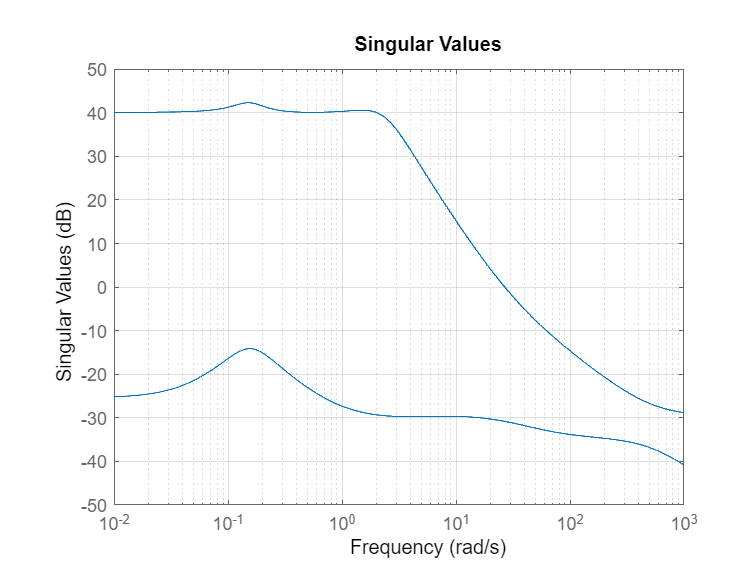

w_range = logspace(-2, 3, 1000); % from 10^-2 to 10^3, 100 points 
sigma(Gn, w_range), grid on

**Calculate **$\mathcal{H}_2$** and **$\mathcal{H}_\infty$** norms of **$G_n(s)$**.**

norm(Gn, 2)

ans = Inf

norm(Gn, "inf")

ans = 130.6905

D_aug = [0 0; 0 0; 0 0];
Gn_aug = ss(A, B, C, D_aug);
norm(Gn_aug, 2)

ans = 103.5397

norm(Gn_aug, "inf")

ans = 130.6903

**Comment on the **$\mathcal{H}_2$** norm. **

$\mathcal{H}_2$-norm can't be calculated for the nominal system, because there is a direct feed through caused by $D \neq 0$. By augmenting the $D$ matrix such that $D = 0$, it is possible to calculate the $\mathcal{H}_2$-norm. For both cases the $\mathcal{H}_\infty$-norm can be calculated, however it differs slightly after augmentation. Beskriv mer varför.

**Ex2 - Baseline controller**

A Linear Quadratic Integrator requires an integral state of one of the system states. This integral state we can create and add to the state-space model, before we use $lqr()$ to calculate the optimal controller. The integral state will look like: $x_i = \int(r_{\alpha} - \alpha)dt \Rightarrow \dot{x}_i = r_{\alpha} - \alpha$.

We first calculate the LQI control matrix $K$ for the extended system:


$$\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{x_i } 
\end{array}\right\rbrack =\underset{A_{\textrm{lqr}} }{\underbrace{\left\lbrack \begin{array}{cc}
A & 0\\
-C\left(1,:\right) & 0
\end{array}\right\rbrack } } \left\lbrack \begin{array}{c}
x\\
x_i 
\end{array}\right\rbrack +\underset{B_{\textrm{lqr}} }{\underbrace{\left\lbrack \begin{array}{cc}
B & 0\\
0 & 1
\end{array}\right\rbrack } } \left\lbrack \begin{array}{c}
u\\
r
\end{array}\right\rbrack$$


The closed loop system with $r$ as reference and LQI control matrix $K$should look like (Given by TA Sondre):


$$\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{x_i } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A & 0\\
-C & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
x_i 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
B\\
0
\end{array}\right\rbrack u+\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
1
\end{array}\right\rbrack r$$


Implementing the control law: $u = -kx_e$, where $x_e$ is the extended state-space vector $\left\lbrack \begin{array}{c}
x\\
x_i 
\end{array}\right\rbrack$. The vector for $r$ is then our new "$B$" matrix.


$$\left\lbrack \begin{array}{c}
\dot{x} \\
\dot{x_i } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
A_{\textrm{lqr}} 
\end{array}\right\rbrack x_e +\left\lbrack \begin{array}{c}
B_{\textrm{lqr}} 
\end{array}\right\rbrack \left(-K\right)x_e +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
1
\end{array}\right\rbrack r=\underset{A_e }{\underbrace{\left\lbrack \begin{array}{c}
A_{\textrm{lqr}} -B_{\textrm{lqr}} K
\end{array}\right\rbrack } } x_e +\underset{B_e }{\underbrace{\left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
1
\end{array}\right\rbrack } } r$$


A_lqr = [A zeros(5, 1);
        -C(1,:) 0];
B_lqr = [B zeros(5, 1); 
        0 0 1];
Q = diag([0 100 0 0 0 1]); % should be calculated by Bryson's rule
R = diag([1 1 1]);       % should be calculated by Bryson's rule
[K, ~, ~] = lqr(A_lqr, B_lqr, Q, R)

K =    -0.0012   15.5368    0.0025    1.5428   -0.0003   -0.9517
    0.0000   -0.3696   -0.0001   -0.0346    0.0000    0.0232
    0.0001   -1.8194   -0.0000   -0.0974    0.0000    0.3061


Now rebuild the new closed loop feedback system.


Ae = [A_lqr-B_lqr*K]; % 6x6
Be = [0 0 0 0 0 1]'; % 6x1
Ce = [C zeros(3, 1)]; % 3x6
De = 0; % 1x1
sys_e = ss(Ae, Be, Ce, De);

t = 0:0.1:100;
r = [zeros(1,200) ones(1,300) zeros(1, 200) ones(1,301)]';
size(r)

ans =         1001           1


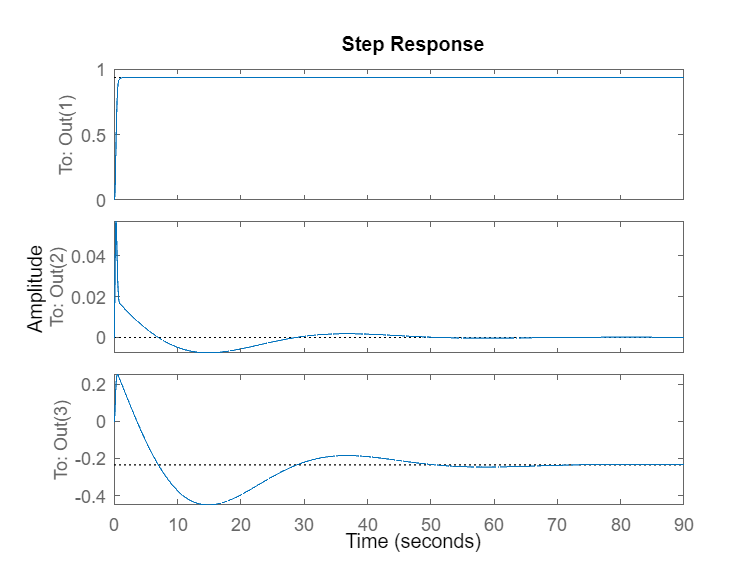

step(sys_e)

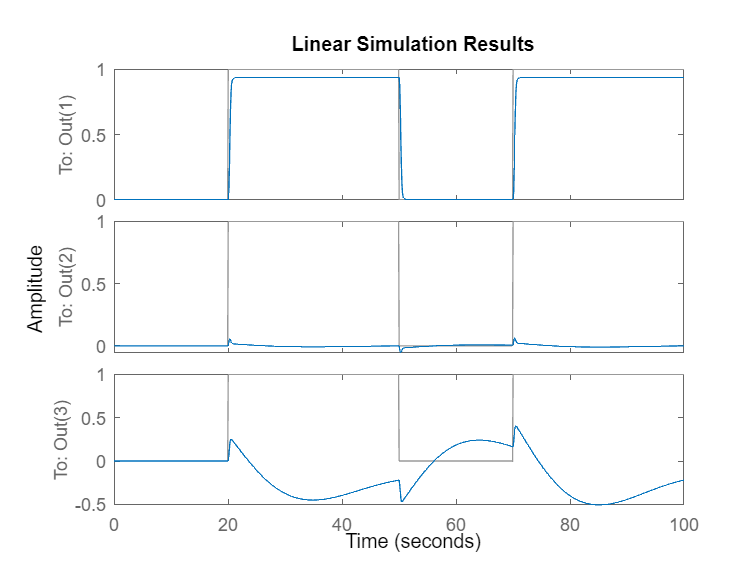

lsim(sys_e, r, t)

**Ex3 - P-K structure**

**Find **$P$**.**

**Identify **$P_{11}$**, **$P_{12}$**, **$P_{21}$**, and **$P_{22}$**.**

**Specify signal dimensions.**


$$dim(u\Delta) = dim(y\Delta) = dim(u) = (1,1)$$



$$dim(v) = (2,1)$$


$dim(w) = dim(z) = (3,1)$